# Live Scripts en Matlab

## ¿Qué es un Live Script?

Los Live Scripts son documentos interactivos que combinan el código de MATLAB con texto, ecuaciones e imágenes en un solo entorno llamado Live Editor. Adicionalmente, estos Live scripts almacenan y muestran la salida junto con el código que la crea (para mayo información visitar [[1]](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html)).

- Para crear Live Scrips con Live Editors diríjase a la tabla de **Home y** seleccione la opción de **New Live Script**.

- Al crear el Live script aparecerá en la barra la opción de **Live editor** e **Insert**, las cuales presentan las opciones de edición de texto e imágenes.

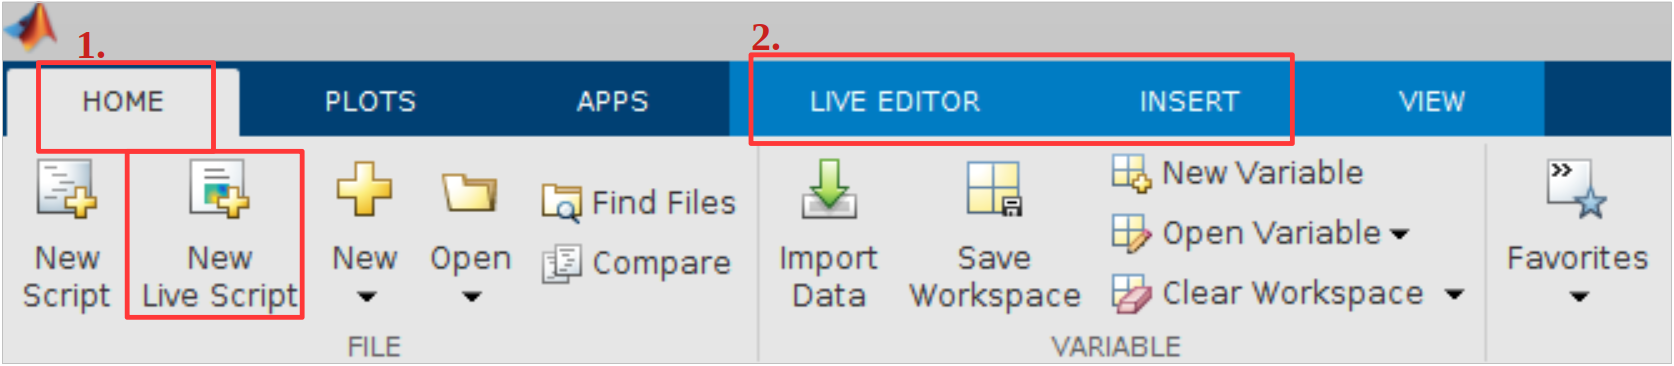

En el archivo de Live Script se puede: 

- Agregar código

- Correr código

- Mostrar la salida del código

- Dar formato a texto

- Agregar imágenes e hipervínculos

Para mayor información ver [[2]](https://www.mathworks.com/help/matlab/matlab_prog/create-live-scripts.html)

# Gráficos y edición avanzada

Volvamos al ejemplo del [taller anterior](https://alexacl95.github.io/EcuacionesDiferencialesLab/HTML/FuncBase.html):

        Graficar la función $f(t)=1+0.5\exp(-0.2 t)\sin(0.8t)$ para $t=[1,60]$

Donde el siguiente código nos entrega el vector resultante de evaluar el vector $t$ en la función $f(t)$

t = 1:1:60; %vetor fila con elementos de 1 a 60
y = 1+0.5*exp(-0.2*t).*sin(0.8*t);

Ahora, para mejorar el gráfico presentado en el [taller anterior](https://alexacl95.github.io/EcuacionesDiferencialesLab/HTML/FuncBase.html), realizaremos los siguientes pasos:

figure %creamos una ventana para nuestra figura

1. Cambiamos el tamaño, color, y forma de la curva al agregar estas propiedades a la función plot:

plot(t,y,'LineWidth',2,'Color','k','LineStyle','--')
% Linewidth: tamaño de la línea
% Color: se define como una letra (negro:k) o código RGB ([0 0 0])
% LineStyle: estilo de la curva, el cual puede ser '--', '*' o '.-'

2. Agregamos una cuadricula (grid) para mejor visualización:

grid on

3. Para agregar los nombres a los ejes debemos definirlos con las siguientes funciones:

xlabel('Tiempo (t)')                %Eje x
ylabel('Variable independiente')    %Eje y   

4. Para agregar un título:

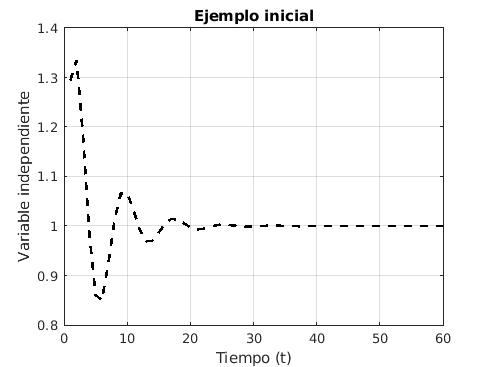

title('Ejemplo inicial')

De esta forma obtenemos un gráfico más elegante y comprensible. Pero, si variar un parámetro de la función $f(t)$, de tal forma que $f_2(t)=1+0.5\exp(-0.8 t)\sin(0.8t)$

¿cómo comparariamos ambos resultados?

## Gráficos comparativos

1. En primer lugar, debemos evaluar el vector $t$ en la nueva función $f_2(t)$. Para ello, definimos un nuevo vector $y2$, que guardará los resultados de $f_2(t)$:

t = 1:1:60; %vetor fila con elementos de 1 a 60
y2 = 1+0.5*exp(-0.8*t).*sin(0.8*t);

2. Graficamos nuevamente el ejemplo anterior $f(t)$:

figure %creamos una ventana para nuestra figura
plot(t,y,'LineWidth',2,'Color','k','LineStyle','--') %gráfico de ejemplo definido para f(t)

3. Agregamos un comando que nos permite superponer gráficos:

hold on

4. Ahora graficamos el resultados de $f_2(t)$ guardados en $y_2$, recordando cambiar el color de la curva:

plot(t,y2,'LineWidth',2,'Color','b','LineStyle','--') %gráfico de ejemplo definido para f_2(t)

5. Agregamos una leyenda para definir cual curva corresponde a $f(t)$ y $f_2(t)$. Note que la primera variable ingresada ({'f(t)', 'f_2(t)'}) corresponde al nombre asignado a cada curva, por lo tanto, se deben ingresar en el orden en que se graficaron. Las demás variables ingresadas (Box y Location) corresponden a detalles estéticos de las curvas (quitar el borde negro que rodea la leyenda y posicionarla de tal manera que no cubra las curvas).

legend({'f(t)', 'f_2(t)'},"Box","off","Location","best")

6. Finalmente agregamos la cuadricula, los nombres de los ejes y el título del gráfico:

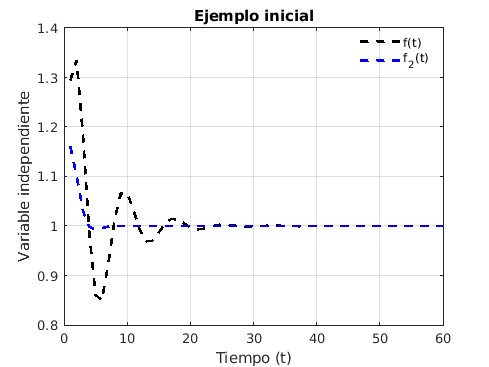

grid on
xlabel('Tiempo (t)')                %Eje x
ylabel('Variable independiente')    %Eje y 
title('Ejemplo inicial')